# Neural Network based Adaptive 

# Control of affine nonlinear uncertain systems

clear; clc;

## NNAC

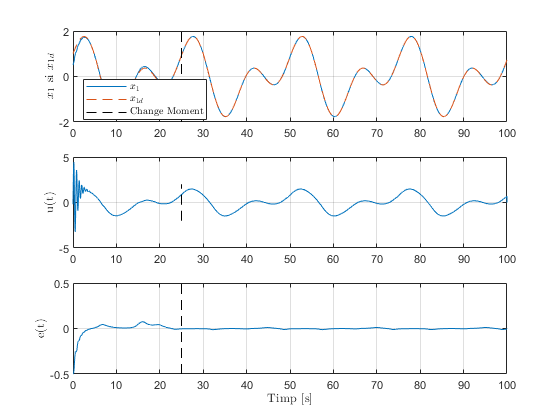

Ts = 0.001;
t = 0:Ts:100;

mu = 0.1;
x0 = [0.5 0.5]';
na = 2;

xd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)]; % desired trajectory initialization


% neural network parameters 
n = 2*na; % number of inputs
m = 20; % number of hidden neurons

% neural network weights initialization
Vc = rands(m, n);
Wc = rands(1, m);

Ac = diag([-1 -1]);
lr = 5;
gamma = 0.001;

% simulation initialization
x = zeros(2, length(t));
e = zeros(2, length(t));
u = zeros(length(t), 1);

x(:, 1) = x0;


aux = floor(length(t)/2)/2;

for i = 1:length(t) - 1
    if i == aux
        %mu = mu + 2;
    end
    e(:, i) = x(:, i) - xd(:, i);
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'/Ac*ones(n/2, 1)*tanh(Vc*x_cnn)';   
    duda = Wc*(eye(m) - diag(tanh(Vc*x_cnn).^2)); % Wc.*tanh_derivative(Vc*x_cnn)'
    dVc = (e(:, i)'/Ac*ones(n/2, 1)*duda)'*x_cnn';
    
    Wc = Wc + Ts*(-lr*dWc - gamma*norm(e(:, 1))*Wc);
    Vc = Vc + Ts*(-lr*dVc - gamma*norm(e(:, 1))*Vc);
    
    % inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    x(:, i + 1) = x(:, i) + Ts*van_der_pol_derivatiave(x(:, i), u(i), mu);    
    %x(:, i + 1) = x(:, i) + Ts*simplified_pendulum(x(:, i), u(i), 0.5);    
end

figure, 
subplot(3, 1, 1);
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
ylabel("$x_1$ si $x_{1d}$", "Interpreter","latex");
legend("$x_1$", "$x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

subplot(3, 1, 2);
plot(t, u); hold on; grid;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
ylabel("u(t)", "Interpreter","latex");

subplot(3, 1, 3);
plot(t, e(1, :)); hold on; grid;
axis([0 t(end) -0.5 0.5])
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("e(t)", "Interpreter","latex");

function dx = van_der_pol_derivatiave(x, u, mu)
    dx = [x(2);
          mu*(1 - x(1)^2)*x(2) - x(1) + u];
end

function dx = simplified_pendulum(x, u, m)
    l = 0.3;
    J = 0.006;
    b = 0.1;
    g = 9.8;
    
    dx = [x(2);
          ((m*g*l)/(J + m*l^2))*sin(x(1)) - (b/(J + m*l^2))*x(2) + (l/(J + m*l^2))*cos(x(1))*u];
end